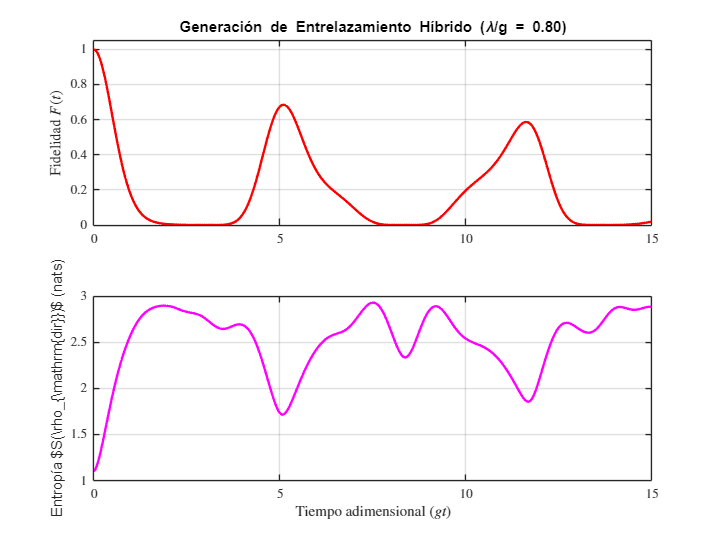

%% MODELO TOE - CÁLCULO DE ENTROPÍA DE VON NEUMANN S(rho_dir)
% Autor: Kilian Hernández Cabrera
% Simulación del Entrelazamiento Híbrido (Qutrits - Osciladores)

clear; clc; close all;

%% 1. PARÁMETROS DEL SISTEMA
hbar = 1; g = 1.0; lambda = 0.8; % Régimen de acoplamiento fuerte
w1 = 1.0; w2 = 1.0; w3 = 1.0;
n_max = 3; 

dim_q = 3; dim_osc = n_max + 1;
dim_q_tot = dim_q^3;       % Dimensión subespacio direcciones (27)
dim_osc_tot = dim_osc^3;   % Dimensión subespacio osciladores (64)
dim_total = dim_q_tot * dim_osc_tot; % 1728

%% 2. OPERADORES BASE
X_q = [0 0 1; 1 0 0; 0 1 0];
a_osc = zeros(dim_osc);
for n = 1:(dim_osc-1), a_osc(n, n+1) = sqrt(n); end
adag_osc = a_osc'; N_osc = adag_osc * a_osc;

I_q = eye(dim_q); I_osc = eye(dim_osc); I_single = eye(dim_q*dim_osc);

%% 3. EXTENSIÓN AL ESPACIO TOTAL
% (Mantenemos la descomposición limpia)
X1 = kron(kron(X_q, I_osc), kron(I_single, I_single));
a1 = kron(kron(I_q, a_osc), kron(I_single, I_single)); adag1 = a1';
N1 = kron(kron(I_q, N_osc), kron(I_single, I_single));

X2 = kron(kron(I_single, kron(X_q, I_osc)), I_single);
a2 = kron(kron(I_single, kron(I_q, a_osc)), I_single); adag2 = a2';
N2 = kron(kron(I_single, kron(I_q, N_osc)), I_single);

X3 = kron(I_single, kron(I_single, kron(X_q, I_osc)));
a3 = kron(I_single, kron(I_single, kron(I_q, a_osc))); adag3 = a3';
N3 = kron(I_single, kron(I_single, kron(I_q, N_osc)));

H0 = hbar*w1*(N1 + 0.5*eye(dim_total)) + ...
     hbar*w2*(N2 + 0.5*eye(dim_total)) + ...
     hbar*w3*(N3 + 0.5*eye(dim_total));
H_dir = (hbar * g / 2) * (X1*X2*X3 + X1'*X2'*X3');
H_osc_dir = hbar * lambda * (X1*adag1 + X1'*a1 + X2*adag2 + X2'*a2 + X3*adag3 + X3'*a3);

H_total = H0 + H_dir + H_osc_dir;

%% 4. ESTADO INICIAL |Psi_0>
v_x = [1;0;0]; v_y = [0;1;0]; v_z = [0;0;1];
v_0 = zeros(dim_osc, 1); v_0(1) = 1;

ket_xyz0 = kron(kron(kron(v_x,v_0), kron(v_y,v_0)), kron(v_z,v_0));
ket_yzx0 = kron(kron(kron(v_y,v_0), kron(v_z,v_0)), kron(v_x,v_0));
ket_zxy0 = kron(kron(kron(v_z,v_0), kron(v_x,v_0)), kron(v_y,v_0));

psi_0 = (1/sqrt(3)) * (ket_xyz0 + ket_yzx0 + ket_zxy0);

%% 5. EVOLUCIÓN TEMPORAL Y TRAZA PARCIAL
t = linspace(0, 15, 300);
[V, D] = eig(H_total);
diag_D = diag(D);
c = V' * psi_0;

F = zeros(size(t));
S_dir = zeros(size(t));

for it = 1:length(t)
    % Estado en el instante t
    psi_t = V * (c .* exp(-1i * diag_D * t(it) / hbar));
    
    % Fidelidad
    F(it) = abs(psi_0' * psi_t)^2;
    
    % Reorganizar el vector ket psi_t en una matriz de dimensión (dim_q_tot x dim_osc_tot)
    % para realizar la Traza Parcial trazando los osciladores rápidamente:
    % rho_dir = Psi * Psi'
    Psi_mat = reshape(psi_t, [dim_osc_tot, dim_q_tot]).'; % Transpuesta para dejar dim_q_tot
    rho_dir = Psi_mat * (Psi_mat'); % Traza parcial sobre el subespacio oscilatorio
    
    % Autovalores de rho_dir para calcular Entropía de Von Neumann
    eig_rho = real(eig(rho_dir));
    eig_rho = eig_rho(eig_rho > 1e-12); % Filtro numérico para evitar log(0)
    
    % S(rho) = - sum( p_i * log(p_i) )
    S_dir(it) = -sum(eig_rho .* log(eig_rho)); 
end

%% 6. GRAFICAR RESULTADOS EN 2 PANELES
figure('Color', [1 1 1], 'Position', [100 100 800 600]);

% Panel Superior: Fidelidad
subplot(2,1,1);
plot(t, F, 'r-', 'LineWidth', 2);
ylabel('Fidelidad $F(t)$', 'Interpreter', 'latex', 'FontSize', 12);
title(sprintf('Generación de Entrelazamiento Híbrido (\\lambda/g = %.2f)', lambda/g), 'FontSize', 14);
grid on; set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 11);
ylim([0 1.05]);

% Panel Inferior: Entropía de Von Neumann
subplot(2,1,2);
plot(t, S_dir, 'm-', 'LineWidth', 2);
xlabel('Tiempo adimensional ($g t$)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Entropía $S(\rho_{\mathrm{dir}})$ (nats)', 'Interpreter', 'latex', 'FontSize', 12);
grid on; set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 11);

% Anotación en la gráfica
text(2, 0.2, '\leftarrow Estado Puro (S=0)', 'FontSize', 10, 'Interpreter', 'latex');